
% Моделеирование с праметрами для верхней точки
% Декремент затухания b = 0
b = 0;
w = 4;
l = 1;
phi = 140;
sim("kapitsa_pendulum.slx");

I = 100

xv0 = x;
yv0 = y;
thetav0 = theta;
dthetav0 = dtheta;

% Моделирование с парметрами для нижней точки
% Декремент затухания b = 0

b = 0;
w = 2;
l = 1;
phi = 30;
sim("kapitsa_pendulum.slx");

I = 100

xn0 = x;
yn0 = y;
thetan0 = theta;
dthetan0 = dtheta;


% Моделеирование с праметрами для верхней точки
% Декремент затухания b = 100
b = 100;
w = 4;
l = 1;
phi = 140;
sim("kapitsa_pendulum.slx");

I = 100

xv = x;
yv = y;
thetav0 = theta;
dthetav0 = dtheta;

% Моделирование с парметрами для нижней точки
% Декремент затухания b = 100

b = 100;
w = 2;
l = 1;
phi = 30;
sim("kapitsa_pendulum.slx");

I = 100

xn = x;
yn = y;
thetan0 = theta;
dthetan0 = dtheta;

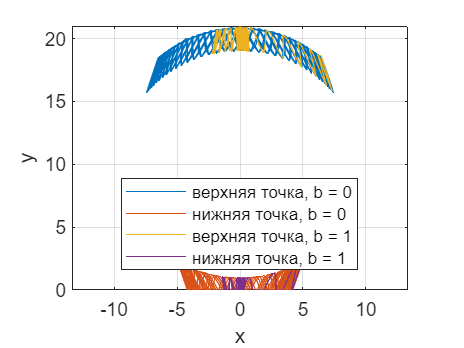

% Обработка результатов
plot(xv0, yv0);
hold on
plot(xn0, yn0);
hold on
plot(xv, yv)
hold on
plot(xn, yn)
axis('equal')
ylabel('y')
xlabel('x')
ylim([0 21])
grid on;
legend('верхняя точка, b = 0', 'нижняя точка, b = 0', 'верхняя точка, b = 1', 'нижняя точка, b = 1', 'Location','best')

% 2 задание
%Частота колебаний подвеса меньше собственной 
% частоты колебаний маятника
b = 0;
w = 0.1;
l = 1;
phi = 120;
sim("kapitsa_pendulum.slx");

I = 100

x2 = x;
y2 = y;
theta2 = theta;
dtheta2 = dtheta;

%Частота колебаний подвеса примерно равна 
% собственной частоте колебаний маятника
b = 0;
w = 1;
l = 1;
phi = 120;
sim("kapitsa_pendulum.slx");

I = 100

x3 = x;
y3 = y;
theta3 = theta;
dtheta3 = dtheta;


%Частота колебаний подвеса много больше 
% собственной частоте колебаний маятника
b = 0;
w = 5;
l = 1;
phi = 140;
sim("kapitsa_pendulum.slx");

I = 100

x4 = x;
y4 = y;
theta4 = theta;
dtheta4 = dtheta;

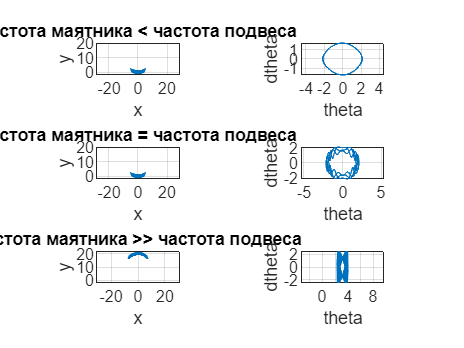

% Обработка результатов
subplot(3,2,1)
plot(xn0, yn0);
ylabel('y')
xlabel('x')
ylim([-2 20])
axis('equal')
title('частота маятника < частота подвеса')
grid on;
subplot(3,2,2)
plot(theta2, dtheta2);
axis('equal')
xlabel('theta')
ylabel('dtheta')
grid on;
subplot(3,2,3)
plot(xn0, yn0);
title('частота маятника = частота подвеса')
ylabel('y')
xlabel('x')
ylim([-2 20])
axis('equal')
grid on;
subplot(3,2,4)
plot(theta3, dtheta3);
xlabel('theta')
ylabel('dtheta')
axis('equal')
grid on;
subplot(3,2,5)
plot(xv0, yv0)
ylim([-2 22])
title('частота маятника >> частота подвеса')
ylabel('y')
xlabel('x')
axis('equal')
grid on;
subplot(3,2,6)
plot(theta4, dtheta4);
xlabel('theta')
ylabel('dtheta')
axis('equal')
grid on;